clear; clc;
close all;
addpath('../functions', '../data')
load proj23.mat

%Import data
Y_Kassala = Kassala;
Y_ELGeneina = ElGeneina;
rain_int = ElGeneina.rain;
rain_org = ElGeneina.rain_org;
t_int = ElGeneina.rain_t;
t_org= ElGeneina.rain_org_t;

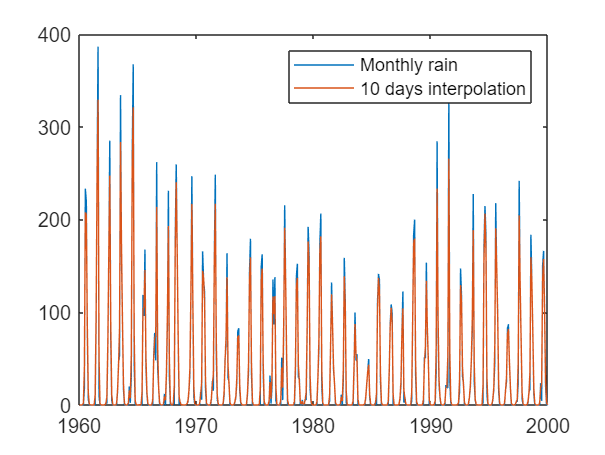

% plot the data and the interpolation /3
figure;
plot(t_org,rain_org)
hold on
plot(t_org,sum(reshape(rain_int/3, 3, [])))
hold off
legend('Monthly rain','10 days interpolation')

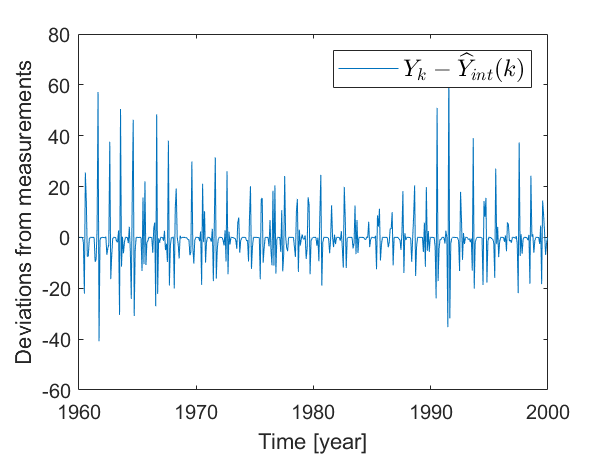

figure;

plot(t_org,(rain_org' - sum(reshape(rain_int/3, 3, []))))
legend('$Y_k -\widehat{Y}_{int}(k)$','Interpreter', 'latex', 'FontSize', 12)
xlabel('Time [year]')
ylabel('Deviations from measurements')

% Calculating totals
mean(rain_org' - sum(reshape(rain_int/3, 3, [])))

ans = -5.5328e-13

sum(abs(rain_org' -sum(reshape(rain_int/3, 3, []))))

ans = 2.7233e+03

sum(rain_org)

ans = 1.7718e+04

sum(rain_int)/3

ans = 1.7718e+04

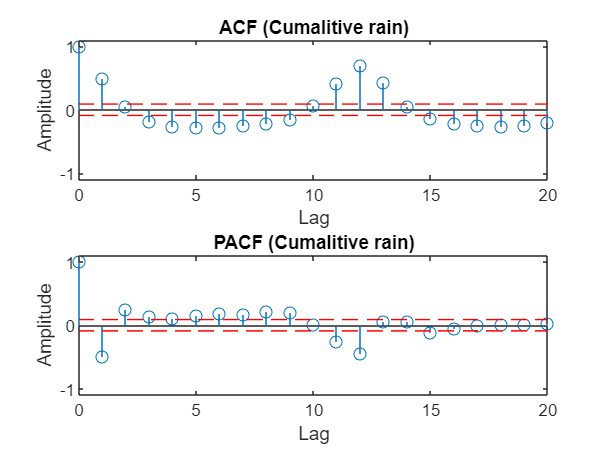

                                                                              
model =                                                                       
Discrete-time AR model: A(z)y(t) = e(t)                                       
  A(z) = 1 - 0.6119 (+/- 0.03614) z^-1                                        
                                                                              
Sample time: 1 seconds                                                        
                                                                              
Parameterization:                                                             
   Polynomial orders:   na=1                                                  
   Number of free coefficients: 1                                             
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.
                                                                              
Status:                                             

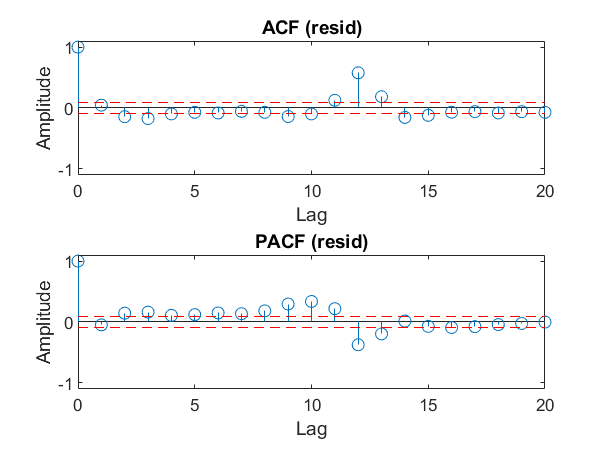

a_est = -0.8490

var_e_est = 527.0405

yt = rain_org;
plotACFnPACF(yt,20,'Cumalitive rain');

Now we try to reconstruct x using a Kalman filter:

yt = xt + xt_m1 + xt_m2 + wt

 States: Xt = [x_{t} x_{t-1} xt_{t-2}]^T with Xt_p1 = a Xt + et

Measurments: yt = [1 1 1]*Xt^T + wt

y = yt;
N = length(y);
var_e_est = 10000;
a_est = 0.8;
ae = a_est;
Re = var_e_est*[1 0 0; 0 1 0; 0 0 1];
Re00 = 1+ae+ae^2;
Re01 = ae+ae^3;
Re02 = ae^2;
Re12 = ae +ae^3;
Re = var_e_est*[Re00 Re01 Re02; Re01 Re00 Re12; Re02 Re12 Re00];
Rw = 0.00001; 

Re =     2.7100    1.6290    0.8100
    1.6290    2.7100    1.6290
    0.8100    1.6290    2.7100


A = (a_est^3)*eye(3); % Use estimated AR parameter 
Rxx_1 = 10* eye(3);  %Initial state variance
xt_t1 = [0 0 0]';      %Initial state values

%Vectors to store values in
Xsave = zeros(3, N);   %Stored states
ehat = zeros(1, N);    %Prediction residual


% Kalman Filter
for t=3:N
    Ct = [1 1 1];  %C_{t|t-1}
    yhat(t) = Ct*xt_t1;  %y_{t|t-1}
    ehat(t) = y(t) - yhat(t);  %e_t = y_t - y_{t|t-1}
    
    %update
    Ryy = Ct * Rxx_1 * Ct' + Rw;     %R^{yy}_{t|t-1}
    Kt = Rxx_1 * Ct' / Ryy;      %K_t
    xt_t = xt_t1 + Kt * ehat(t);   %x_{t|t}
    Rxx = Rxx_1 - Kt * Ct * Rxx_1;      %R{xx}_{t|t}
    
    %Predict the next state
    xt_t1 = A * xt_t;   %x_{t+1|t}
    Rxx_1 = A * Rxx * A' + Re;    %R^{xx}_{t+1|t}
    
    %Store the state vector
    Xsave(:, t) = xt_t;
    

end

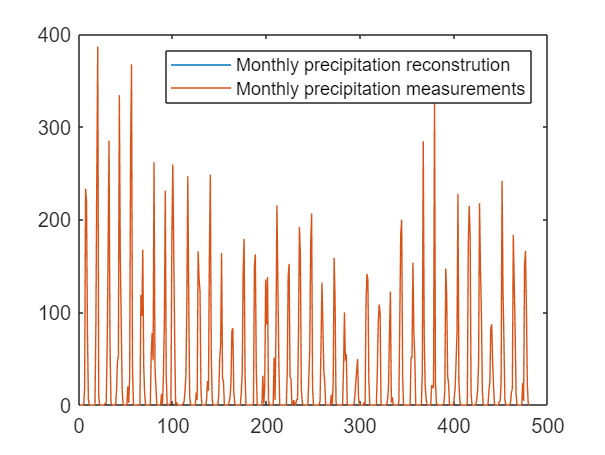

% There are two checks that need to be satisfied by our reconstruction
% Check 1: Recreate the rain measurments by summing up every 3 values of
% our rain reconstruction and see if that aligns with the actual rain data
figure;
plot(sum(Xsave)) 
hold on
plot(y)
hold off
legend('Monthly precipitation reconstrution','Monthly precipitation measurements')

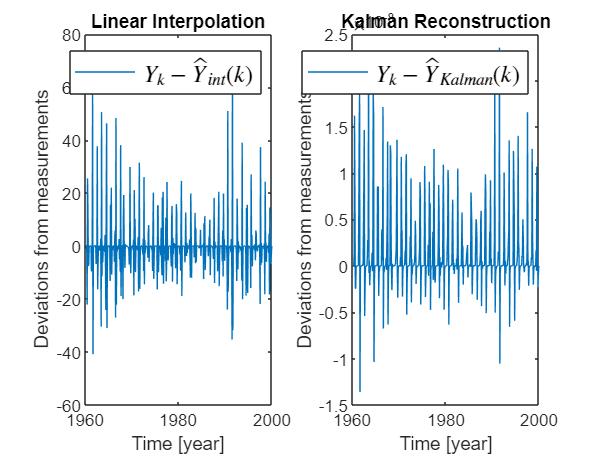


subplot(1, 2, 1);
plot(t_org,rain_org' - sum(reshape(rain_int/3, 3, [])))
legend('$Y_k -\widehat{Y}_{int}(k)$','Interpreter', 'latex', 'FontSize', 12)
xlabel('Time [year]')
ylabel('Deviations from measurements')
title('Linear Interpolation')
subplot(1,2, 2);
plot(t_org,y'-sum(Xsave))
legend('$Y_k -\widehat{Y}_{Kalman}(k)$','Interpreter', 'latex', 'FontSize', 12)
xlabel('Time [year]')
ylabel('Deviations from measurements')
title('Kalman Reconstruction')

sum(abs(y'-sum(Xsave)))

ans = 1.0357e-06

sum(abs(rain_org' - sum(reshape(rain_int/3, 3, []))))

ans = 2.7233e+03

ans = -2.3111e-33

% Check 2: The total amount of rain should not change (us adding new
% measurment points should not change the amount of real rain)
y_rec = sum(Xsave); % Reconstructed Cumulative rain
sum(y_rec) % total reconstructed rain

ans = 1.7718e+04

sum(y)-sum(y_rec) % real amount of rain

ans = 6.2439e-07

% Total amount of rain matches! yeay
sum(y)-sum(rain_int/3)

ans = -2.6193e-10

sum(rain_int/3) 

ans = 1.7718e+04

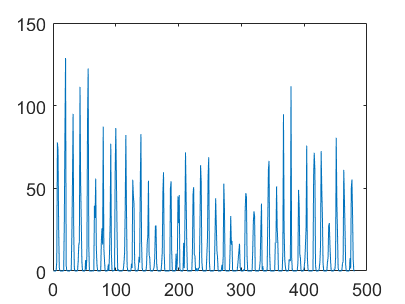

plot(Xsave(3,:)) % Xsave() is x_t, x_(t_1) and x_(t_3)

% Compare our KF reconstructed rain vs the linear interpolated rain

figure
x_restored = reshape(Xsave, 1, []);

ans = -1.2995e-15

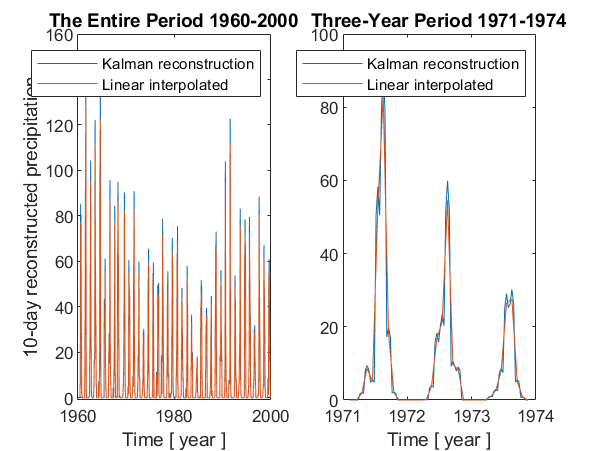

subplot(1, 2, 1);
plot(t_int,x_restored)
hold on
plot(t_int,rain_int/3)
hold off
ylim([-1,160])
legend('Kalman reconstruction','Linear interpolated')
title('The Entire Period 1960-2000')
ylabel('10-day reconstructed precipitation')
xlabel('Time [ year ]')
subplot(1, 2, 2);
plot(t_int(400:500),x_restored(400:500))
hold on
plot(t_int(400:500),rain_int(400:500)/3)
hold off
legend('Kalman reconstruction','Linear interpolated')
title('Three-Year Period 1971-1974')
xlabel('Time [ year ]')

Now we make a model for the rain

x = x_restored;
x(x < 0) = 0 % ignore negative rain

x =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    5.4551    6.2898    5.4551   73.9612   85.2776   73.9612   69.5844   80.2312   69.5844   24.9603   28.7794   24.9603    1.9347    2.2307    1.9347    0.0000    0.0000    0.0000         0    0.0000         0         0    0.0000         0         0    0.0000         0         0    0.0000         0         0    0.0000         0         0    0.0000


sum(x)

ans = 1.7718e+04

% Check 2: The total amount of rain should not change (us adding new
% measurment points should not change the amount of real rain)
y_rec = sum(Xsave); % Reconstructed Cumulative rain
sum(x) % total reconstructed rain

ans = 1.7718e+04

sum(y)-sum(y_rec) % real amount of rain

ans = 6.2439e-07

% Total amount of rain matches! yeay
sum(y)-sum(rain_int/3)

ans = -2.6193e-10

sum(rain_int/3) % The interpolated data clearly fails this test

ans = 1.7718e+04

sum(x)

ans = 1.7718e+04

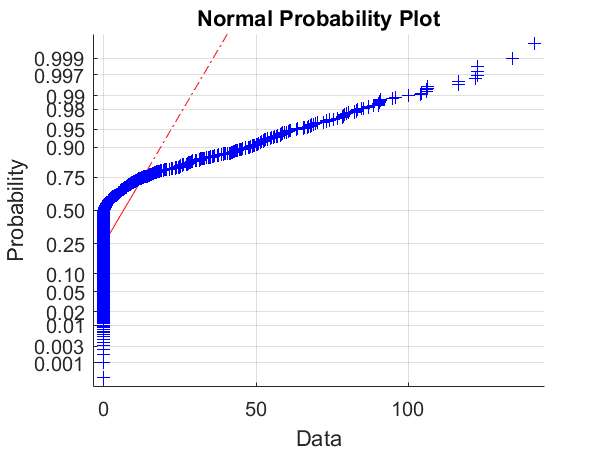


% try different transformations to obtain normal data
normplot(x);

The D'Agostino-Pearson's K2 test indicates that the rain is NOT normal distributed.


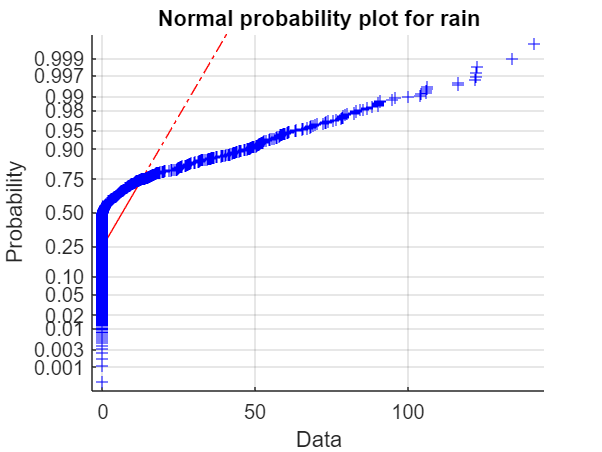

ans = logical
   0


checkIfNormal(x,'rain')


logx = log(x_restored+6)

logx =     1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    2.4384    2.5088    2.4384    4.3815    4.5139    4.3815    4.3252    4.4570    4.3252    3.4327    3.5490    3.4327    2.0712    2.1079    2.0712    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918    1.7918


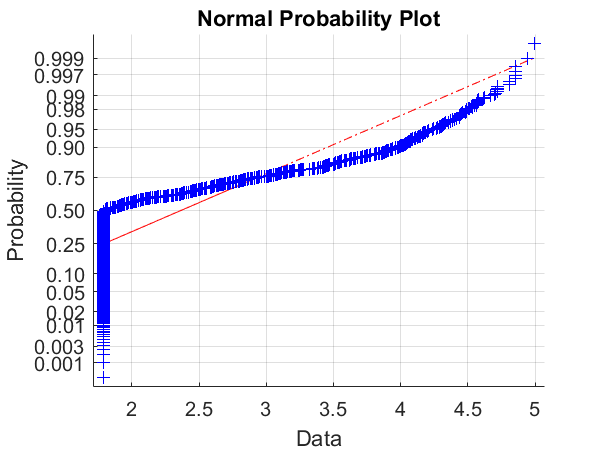


% alternative transform (similar result)
lambda = 0.4;  % You can try different values for lambda
xup04 = (x.^0.4 - 1) / 0.4;


figure;
normplot(logx)

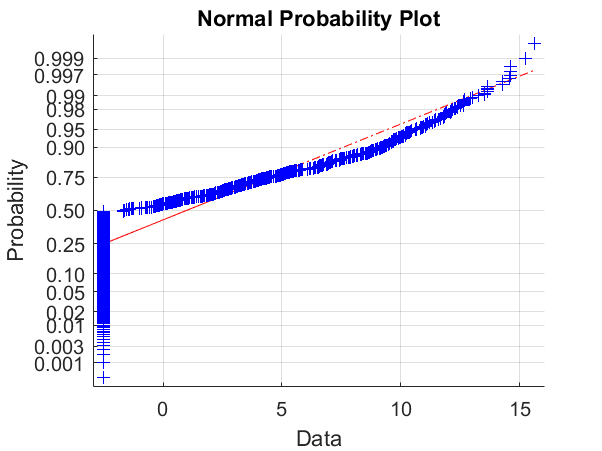


figure
normplot((xup04))

% Subtract the mean
x = log(xup04- mean(xup04)+6)

x =     0.7908    0.7908    0.7908    0.7908    0.7908    0.7908    0.7908    0.7908    0.7908    0.7908    0.7908    0.7908    0.7908    0.7908    0.7908    1.9647    2.0044    1.9647    2.7842    2.8335    2.7842    2.7631    2.8123    2.7631    2.4212    2.4672    2.4212    1.6975    1.7319    1.6975    0.7909    0.7909    0.7909    0.7908    0.7908    0.7908    0.7908    0.7908    0.7908    0.7908    0.7908    0.7908    0.7908    0.7908    0.7908    0.7908    0.7908    0.7908    0.7908    0.7908


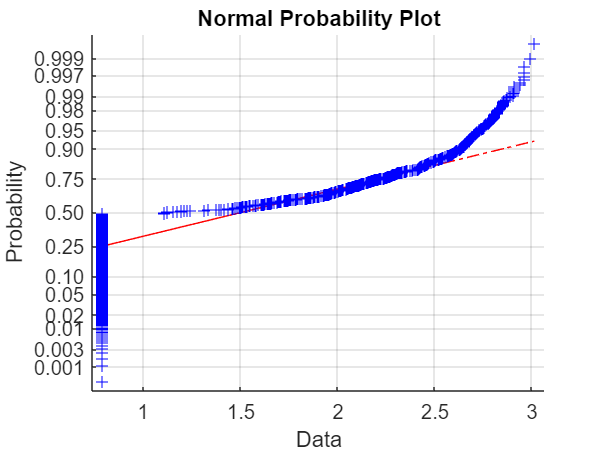

normplot(x)

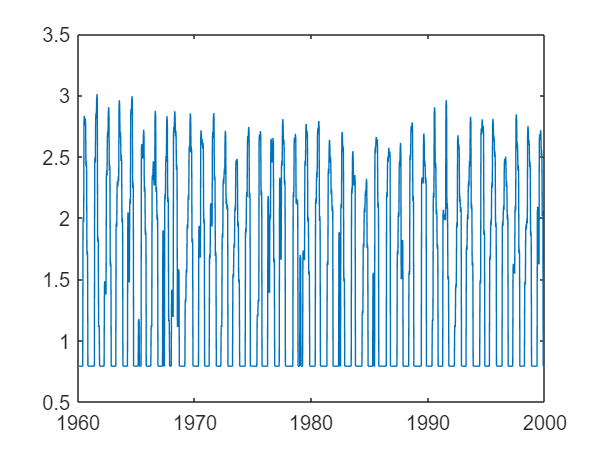

plot(t_int,x)

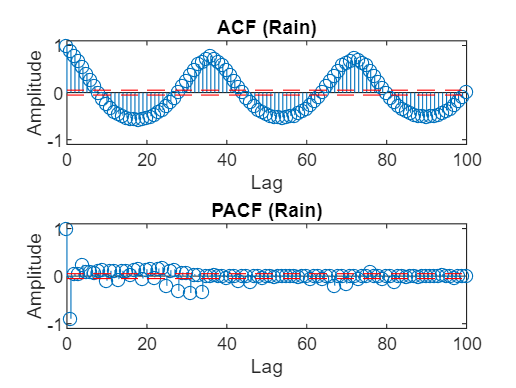

ans =     1.0000    0.8968    0.7936    0.6904    0.5528    0.4152    0.2777    0.1409    0.0041   -0.1327   -0.2244   -0.3162   -0.4080   -0.4500   -0.4920   -0.5340   -0.5455   -0.5570   -0.5685   -0.5462   -0.5239   -0.5016   -0.4565   -0.4114   -0.3663   -0.2779   -0.1894   -0.1010    0.0201    0.1411    0.2622    0.3772    0.4922    0.6071    0.6648    0.7225    0.7802    0.7224    0.6646    0.6067    0.4911    0.3755    0.2599    0.1395    0.0190   -0.1015   -0.1843   -0.2672   -0.3500   -0.3951


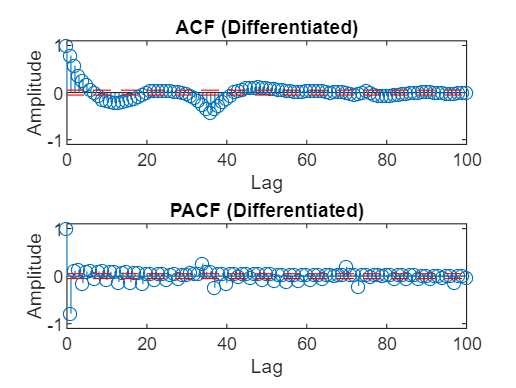

ans =     1.0000    0.7882    0.5764    0.3646    0.2647    0.1649    0.0650   -0.0035   -0.0720   -0.1404   -0.1655   -0.1906   -0.2156   -0.2021   -0.1886   -0.1751   -0.1464   -0.1177   -0.0891   -0.0474   -0.0058    0.0358    0.0387    0.0415    0.0444    0.0408    0.0373    0.0338    0.0181    0.0025   -0.0132   -0.0612   -0.1093   -0.1573   -0.2483   -0.3392   -0.4301   -0.3479   -0.2656   -0.1834   -0.1178   -0.0522    0.0133    0.0422    0.0710    0.0998    0.1066    0.1134    0.1201    0.1100


resid =    -3.6951
   -0.3357
   -0.3417
   -2.3408
   -0.4960
   -0.4536
   -2.0923
   -0.6074
   -0.6345
   -2.1631


                                                                                                                                     
model =                                                                                                                              
Discrete-time ARMA model: A(z)y(t) = C(z)e(t)                                                                                        
                                                                                                                                     
  A(z) = 1 + 0.01187 (+/- 0.03047) z^-1 - 0.239 (+/- 0.03871) z^-2 - 0.01782 (+/- 0.02424) z^-8 + 0.1065 (+/- 0.0246) z^-9 + 0.1075 (
                           +/- 0.02675) z^-11 - 0.3159 (+/- 0.03906) z^-35 + 0.2552 (+/- 0.03753) z^-36 + 0.1734 (+/- 0.02785) z^-37 
                                                                                                                                     
                                                              

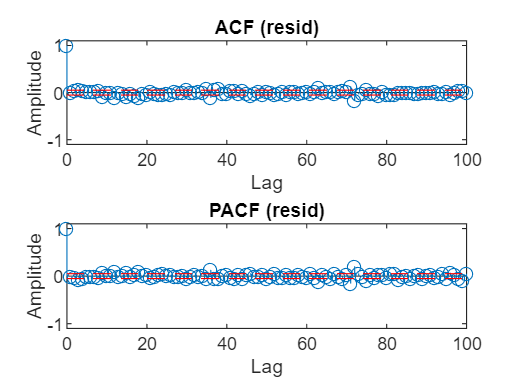

ans =     1.0000
    0.0079
    0.0379
    0.0663
    0.0471
    0.0233
    0.0236
    0.0244
    0.0380
   -0.0729


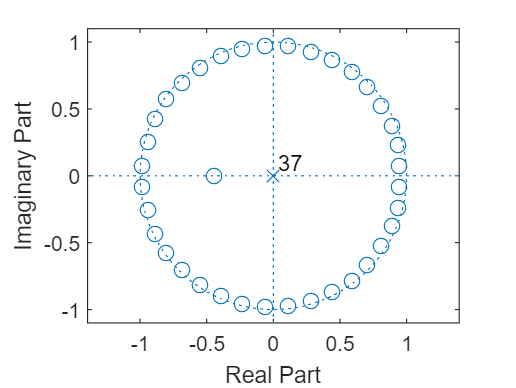

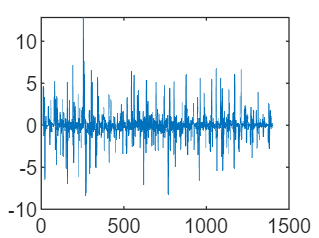

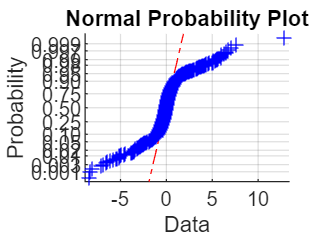

Whiteness test with 5% significance
  Ljung-Box-Pierce test: 1 (white if 36.39 < 36.42)
  McLeod-Li test:        0 (white if 435.23 < 36.42)
  Monti test:            1 (white if 36.08 < 36.42)
  Sign change test:      1 (white if 0.52 in [0.47,0.53])


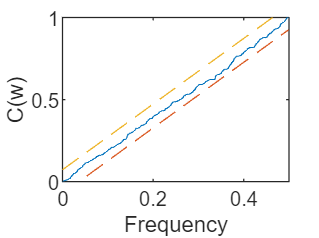



transformed_rain2 = x;
